# Quickstart

This guide describes how to create a new project from a template and perform a few basic operations

## Define project location and name

The first thing to do when creating a project is to define a location and a project name. The location will become the parent directory of the project, and the project name will be used for the project directory and as a prefix on most project files.

rootDir = 'C:\newdepomod_projects\';

if ~exist(rootDir, 'dir')
    mkdir(rootDir);
end

projectName = 'bay_of_fish';


## Create project

Create a new project from a template, according to the location and name specified

project = NewDepomod.Project.createFromTemplate(rootDir, projectName)

Copying Depomod files: 
    FROM: C:\Users\andrew.berkeley\Documents\MATLAB\InstalledPackages\depomod_toolbox\versions\dev\depomod_toolbox\lib\Templates\template
    TO:   C:\newdepomod_projects\template
originalPath =
  0×0 empty char array


locationFilePath = 'C:\newdepomod_projects\template\depomod\models\template.depomodlocationproperties'

filesToSub = 'C:\newdepomod_projects\template\depomod\private\depomod.prj'

project =   Project with properties:

       version: 2
      location: [1×1 NewDepomod.PropertiesFile]
    bathymetry: [1×1 NewDepomod.BathymetryFile]
     flowmetry: [1×1 NewDepomod.FlowmetryFile]
          name: 'bay_of_fish'
          path: 'C:\newdepomod_projects\bay_of_fish'
    solidsRuns: [1 Depomod.Run.Collection]
      EmBZRuns: [1 Depomod.Run.Collection]
      TFBZRuns: [1 Depomod.Run.Collection]

This creates a new project complete with all required files. It also returns a Matlab object which represents the project. Notice there includes 1 solids run and 1 EmBZ run, as well as objects describing the bathymetry and flow data

## View the bathymetry

Plot the raw, cell-by-cell water depths

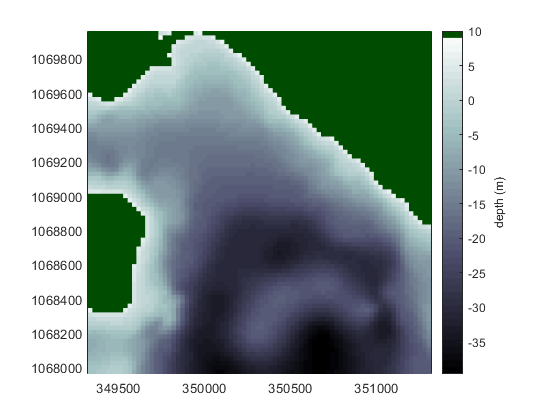

figure;
project.bathymetry.plot

Or plot the bathymetry as contours

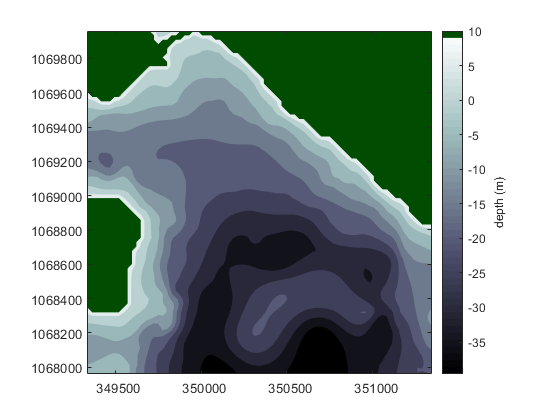

figure;
project.bathymetry.plot('contour',1)

## Inspect solids run

We can inspect the single solids run that we have.

Retrieve the first organic solids run:

run = project.solidsRuns.item(1)

run =   Solids with properties:

                     modelFile: [1×1 NewDepomod.PropertiesFile]
        physicalPropertiesFile: [1×1 NewDepomod.PropertiesFile]
             configurationFile: [1×1 NewDepomod.PropertiesFile]
                   runtimeFile: [1×1 NewDepomod.PropertiesFile]
                    inputsFile: [1×1 NewDepomod.InputsPropertiesFile]
           iterationInputsFile: [0×0 NewDepomod.InputsPropertiesFile]
        exportedTimeSeriesFile: [0×0 NewDepomod.TimeSeriesFile]
    consolidatedTimeSeriesFile: [0×0 NewDepomod.TimeSeriesFile]
                     solidsSur: [0×0 Depomod.Sur.Solids]
                     carbonSur: [0×0 Depomod.Sur.Solids]
                         label: '1'
            iterationRunNumber: []
                 modelFileName: 'bay_of_fish-1-NONE.depomodmodelproperties'
                          tide: 'N'
                   resultsPath: 'C:\newdepomod_projects\bay_of_fish\

This returns a Matlab object that represents the model run. Notice this object references all of the input (e.g. cages, inputs, physical) files and all of the output files (sur(face), time series) which will be written when the model is executed. This object can be used to navigate all of the information related to a particular run.

We can also inspect some of the details which are stored in the run files. For example, find the configured biomass (t) or stocking density (kg/m3)

run.inputsFile.FeedInputs.biomass

ans = '1000'

run.inputsFile.FeedInputs.stockingDensity

ans = '13.0826'

And some of the physical parameters in the physical properties file

run.physicalPropertiesFile.Transports.bottomRoughnessLength.smooth

ans = '0.00003'

run.physicalPropertiesFile.Transports.resuspension.walker.dispersionCoefficientX

ans = '0.1'

We can retreive some information about the cages

run.cages.sizeCages  % count

ans =      8

run.cages.cageArea   % m2

ans =           6369.80278655024

run.cages.cageVolume % m3

ans =           76437.6334386029

Plot the cages

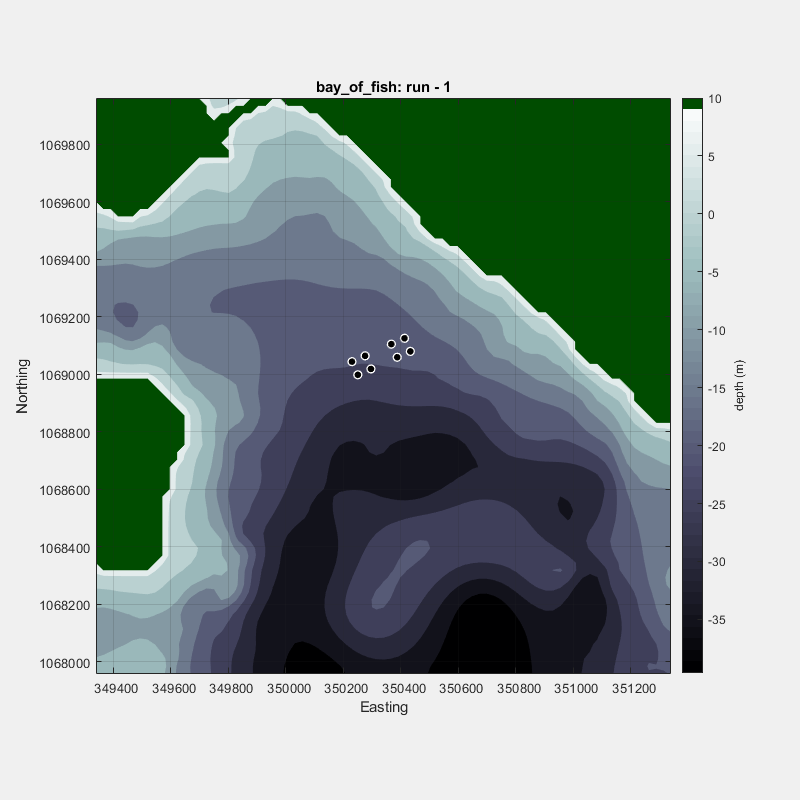

run.plot;

## Execute run

This executes the run using the command line execution framework via a new terminal window

run.execute;

Starting simulation...
Command: "C:\Program Files\depomodruntimecontainer\bin\depomodruntimecontainer" --modelRunTimeFile "C:\newdepomod_projects\bay_of_fish\depomod\models\bay_of_fish-1-NONE.depomodruntimeproperties" --nosplash --singleRunOnly --showConsoleOutput --showConsoleProgress
Time: 03-Jun-2019 08:34:19
Elapsed time is 1.027387 seconds.


## Read output files

Once the model run has completed we can read some output files.

We can read the logfile to check how much material was discharged in total (g)

run.log.Masses.solids.released.run

ans = '408046275.0000'

and compare with mass remaining in domain (g; the difference was exported)

run.log.Masses.solids.balance.run

ans = '403574534.9947'

We can measure the predicted area of a specific level of deposition (e.g. 250 g m-2) in m2

run.solidsSur.area(250)

ans =           56878.5241655428

We can find the predicted level of deposition at a specific location (easting/northing) in g m-2

run.solidsSur.valueAt(350400,1069000)

ans =           166.746001879835

And we can plot the impact

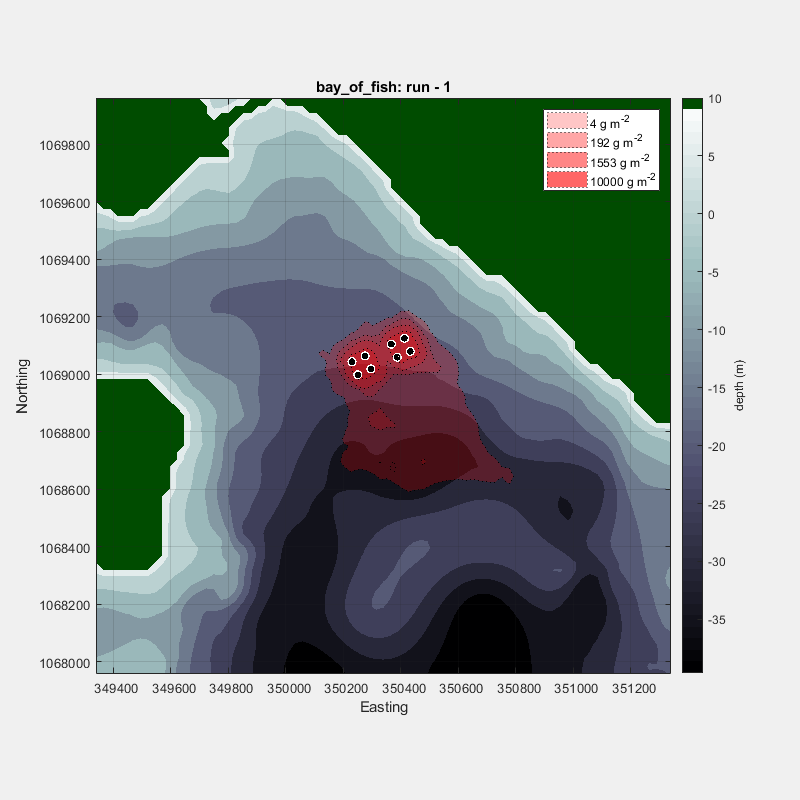

run.plot;